# MXB161 IW7 Random Walks

This is your individual worksheet.  Complete this worksheet at your own pace.  After you've completed the worksheet, you'll be ready to take the Quiz for this topic, linked on Canvas.

## 7.1 A simple experiment: tossing a coin

Suppose you want to simulate a coin toss. The coin comes up heads 50% of the time, and tails the other 50% of the time. How can we do this in MATLAB? One way is to generate a random number **r** between 0 and 1. If **r** < 0.5 then declare the outcome to be `'``H``'`, otherwise declare the outcome to be `'``T``'`.

Having watched the video, try to write the code below yourself, replicating what you saw in the video.  If you get stuck, refer back to the video.  The solution is also given further down the page if you really get stuck.

r = rand;          % generate a random number between 0 and 1
if r < 0.5         % if r is less than 0.5
    outcome = 'H'  % declare the outcome to be 'H'
else               % otherwise
    outcome = 'T'  % declare the outcome to be 'T'
end

outcome = 'H'

Run the code a few times and confirm you get 'H' about half the time, and 'T' about half the time.

The code you write will use the **if**, **else**, **end** structure.  This is something new for us.  It's called (perhaps unsurprisingly) an *if statement*, and it's the standard way to decide between multiple alternatives for "what to do next" in MATLAB.

In fact, the MATLAB code very much resembles our English description of the algorithm.

English:

Generate a random number **r** between 0 and 1.  If **r** is less than 0.5 declare the outcome to be `'``H'`, otherwise declare the outcome to be `'``T'`.

MATLAB:

The biggest difference is perhaps that MATLAB uses the word **else** rather than "otherwise".

Suppose you wanted to *bias* the coin toss.  How would you alter the code so that the coin comes up heads with probability **p**, where **p** can be chosen as any value between zero and one?  Alter the code to include this extension, and set the value of **p** such that heads is twice as likely as tails.  Run the code 10 times.  Do you see the bias reflected in the outcomes?

r = rand;          % generate a random number between 0 and 1
p = 0.2;
if r < p         % if r is less than 0.5
    outcome = 'H'  % declare the outcome to be 'H'
else               % otherwise
    outcome = 'T'  % declare the outcome to be 'T'
end

outcome = 'T'

**Well done on finishing this section**.  Now you can return to the online lecture.

## 7.2 One-dimensional random walks

A random walk is a particular mathematical model describing particles that move about "randomly" (in a sense that will be made more precise as we go on). Random walks are interesting in their own right, but also of great importance as models of real-world applications including stock markets and diffusion processes. In this section we will consider random walks in one dimension. The basis of a random walk is a particle that continually "jumps" around at random. In a one-dimensional random walk, the particle is jumping back and forth on the **x**-axis. At any instant the particle randomly chooses whether in the next instant it will jump left or jump right. Then it makes the jump, and the process repeats. Suppose we denote the particle's position at time instant $n$ by $x_n$. Then the basic algorithm for a 1D random walk is as follows: 

1. Place the particle at the initial location $x_1$. 

2. Move the particle one unit left with probability $p$, and one unit right with probability $1-p$, to produce $x_2$. 

3. Repeat step 2 to produce $x_3$, $x_4$,.... 

The figure below illustrates the $n$-th iteration of this algorithm graphically. The distance that the particle can jump is denoted $\Delta$ (capital Delta). In the figure, the particle will jump to position $x_n-\Delta$with probability $p$ and to $x_n+\Delta$with probability $1-p$. Whichever jump is taken, the new position is labelled $x_{n+1}$. 

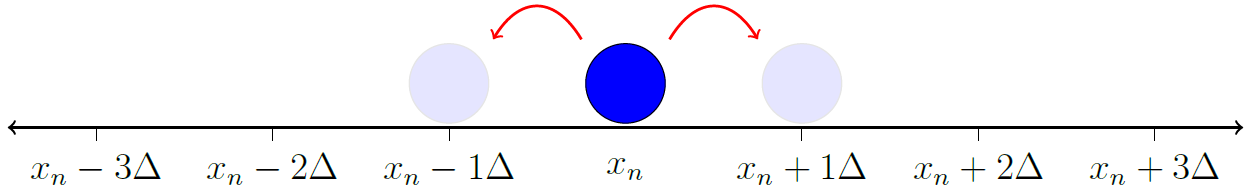

Suppose that the particle jumped to the left, so that $x_{n+1} = x_n - \Delta$. This would result in the configuration for the $(n+1)$-th step shown below. We now repeat the same procedure to in order to determine $x_{n+2}$.

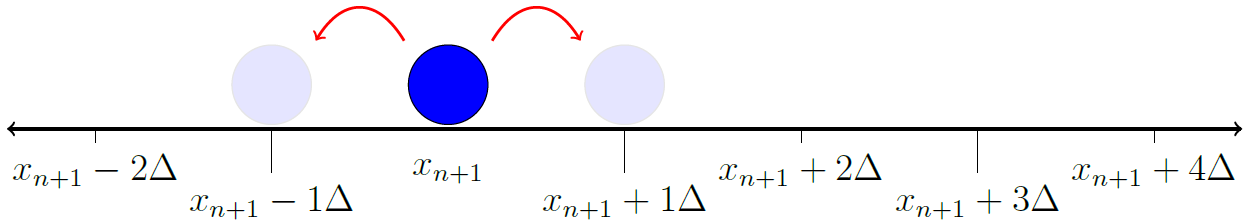

Having watched the lecture video, you have seen how to adapt your coin flipping code above to instead perform a random walk simulation.  Do this now, referring back to the video if you get stuck.  At first, you just want to implement a random walk for a **single particle**, and produce a plot at the end.  You're aiming to produce a figure like so:

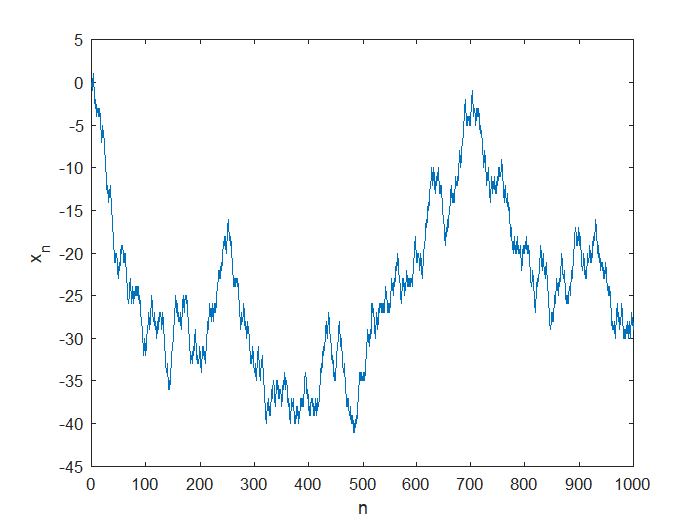

steps     = 1000;   % number of steps
p         = 0.5;    % probability of jumping left
Delta     = 1;      % size of jump

x = zeros(1, steps+1);

% Code to perform random walk goes here
current = 0;
for n = 1:steps + 1
    r = rand;   % random number between 0 and 1
    if r < p
        current = current + Delta;
    else
        current = current - Delta;
    end
    x(n) = current;
end

plot(x)


% Code to produce figure goes here

An alternative to plotting the particle's position against the step, is just to animate the particle jumping around.

figure
L = max(abs(x));                          % the furthest position the particle reached
for n = 1:steps+1
    plot(x(n), 0, '.', 'MarkerSize', 20)  % plot the particle
    xlim([-L, L])                         % set the axes correctly
    drawnow                               % yes, really draw it please MATLAB
end

Do you think your particle feels lonely all by itself?

### Several particles

Let's give our particle some company.  Take your code from above, and paste it in this section.  Then, adapt the code as you saw in the lecture video, to perform a random walk for **multiple particles**.  

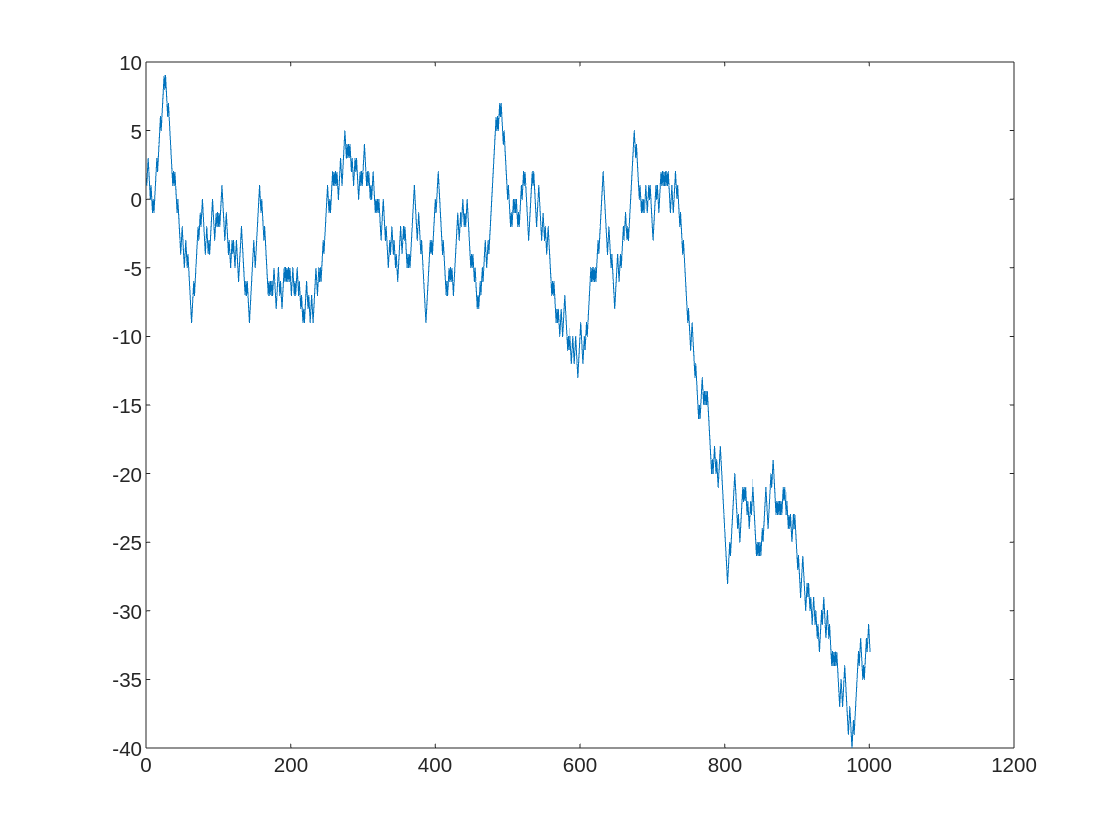

particles = 10;     % number of particles

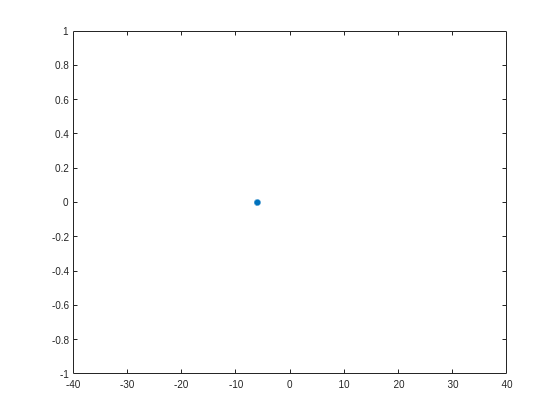

steps     = 1000;   % number of steps
p         = 0.5;    % probability of jumping left
Delta     = 1;      % size of jump

figure

x = zeros(particles,steps+1);

% Code to perform random walk goes here
for n = 1:steps
    for m = 1:particles
        r = rand;	% random number between 0 and 1
        if r < p

            x(m, n+1) = x(m, n) - Delta;	% jump left
        else
            x(m, n+1) = x(m, n) + Delta;	% jump right
        end
    end
end

figure
plot(0:steps, x)
xlabel('n')
ylabel('x_n')

figure
L = max(abs(x(:)));                        % the furthest position any particle reached
for n = 1:steps+1
    plot(x(:,n), 0, '.', 'MarkerSize', 20) % plot the particles
    xlim([-L, L])                          % set the axes correctly
    drawnow                                % yes, really draw it please MATLAB
end

Although the particles all begin at the origin, over time they drift apart.  Unfortunately this animation can be misleading, since whenever two particles occupy the same location, they'll be plotted directly on top of one another.  So, you won't always see ten distinct particles on screen at once.  We'll fix that in the next section.

**Well done on finishing this section**.  Now you can return to the online lecture.

## 7.3 Taking things to the limit

### Another way to visualise

In the animation you created in the previous section, it's impossible to know precisely *how many* particles are at a given position (unless it's zero) since multiple particles might be sitting on top of one another at any step.  This clearly doesn't scale well with lots of particles.  A better idea might be to use a *histogram*, which reveals the *counts* of how many particles are at each location. Here's how to do it.

First, run your simulation this time with 1000 particles for 200 steps.

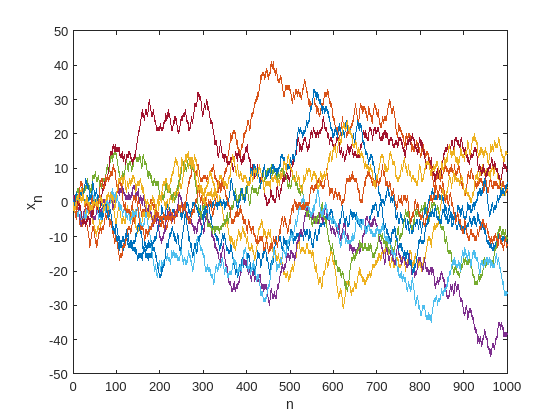

particles = 1000;     % number of particles
steps     = 200;   % number of steps
p         = 0.5;    % probability of jumping left
Delta     = 1;      % size of jump

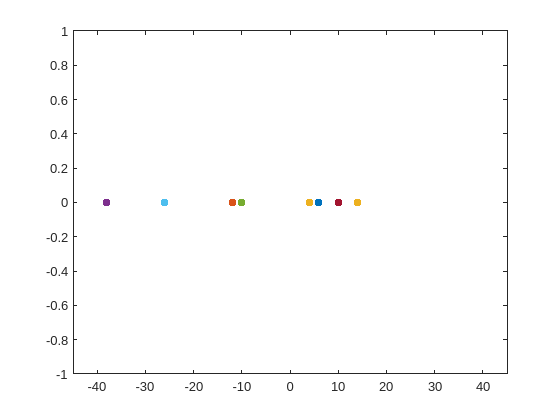


figure

x = zeros(particles,steps+1);

% Code to perform random walk goes here
for n = 1:steps
    for m = 1:particles
        r = rand;	% random number between 0 and 1

        if r < p
            x(m, n+1) = x(m, n) - Delta;	% jump left
        else
            x(m, n+1) = x(m, n) + Delta;	% jump right
        end
    end
end

figure
plot(0:steps, x)
xlabel('n')
ylabel('x_n')

You should have a 1000x201 array **x** of positions in your workspace.  We calculate the furthest position that any particle reached:

L = max(abs(x(:))) % the furthest position any particle reached

Now you can plot a histogram of the *initial* particle distribution as follows (remember that each *column* of **x** is a snapshot of the particle distribution at a given time):

figure
xlabel('Position x_n')
ylabel('Count')
title('Steps Up To = 200');
for i = 1:steps + 1
    histogram(x(:,i), -L:2*Delta:L) % each bin covers a width of two steps for averaging
    drawnow
end

The histogram simply confirms that *every* particle begins at **x** = 0 (i.e. the count is 1000 at **x** = 0, and zero everywhere else).  But what about at some later time?  Make a slider to visualise the histogram at any value of **n, **and use this to confirm it approaches a bell curve shape.

% YES

# Exercises

1. Update your code for the histogram to produce an *animation* of the histogram over time, rather than using a slider.

2. Implement a random walk in two dimensions, following the example in the lecture video.  Choose from a static image, a slider, or an animation to visualise the results.  Or try all three!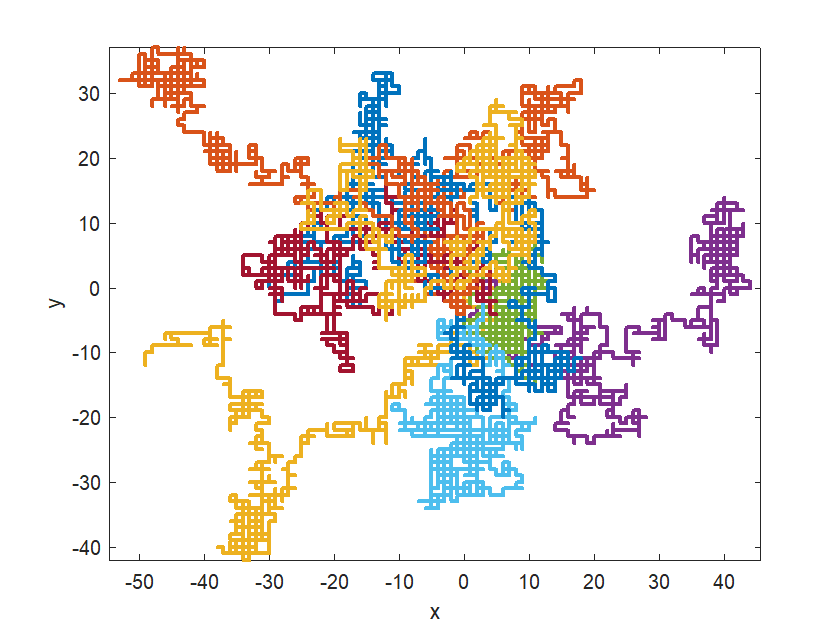

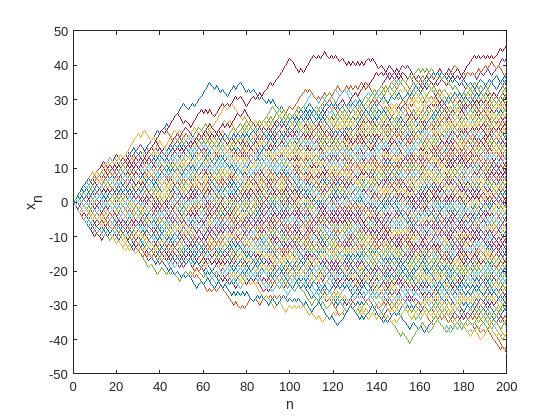

particles = 10;     % number of particles
steps     = 1000;   % number of steps
p         = 0.5;    % probability of jumping left
j = 0.5;

Delta     = 1;      % size of jump


L = 46

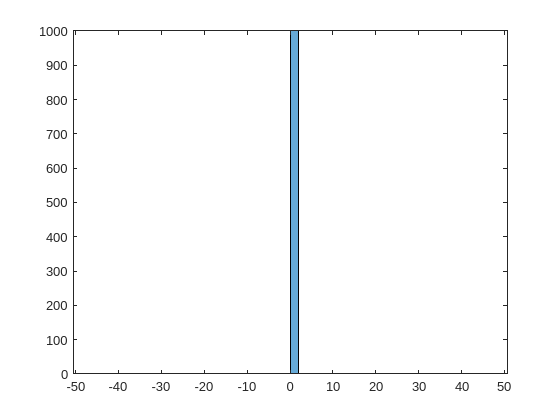

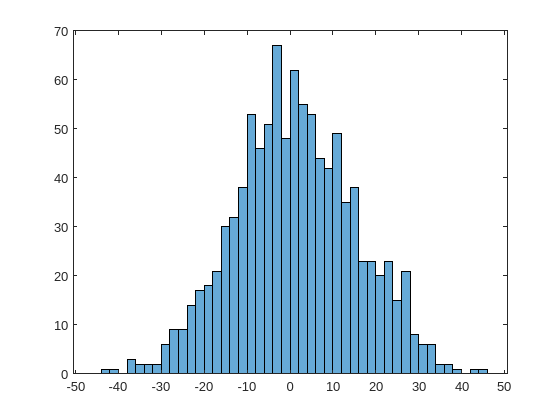

figure

x = zeros(particles,steps+1);
y = zeros(particles,steps+1);

% Code to perform random walk goes here
for n = 1:steps
    for m = 1:particles
        d = rand;

        xyRand = rand;
        if xyRand < j
            y(m, n+1) = y(m, n);
            if d < p
                x(m, n+1) = x(m, n) - Delta;	% jump left
            else
                x(m, n+1) = x(m, n) + Delta;	% jump right
            end
        else
            x(m, n+1) = x(m, n);
            if d < p
                y(m, n+1) = y(m, n) - Delta;	% jump down
            else
                y(m, n+1) = y(m, n) + Delta;	% jump up
            end
        end
    end
end

figure
plot(y', x')
xlabel('n')
ylabel('x_n')

3.  Experiment with creating a 2D histogram for your 2D random walk.  Try the `histogram2` function.  Be sure to have lots of particles taking lots of steps.

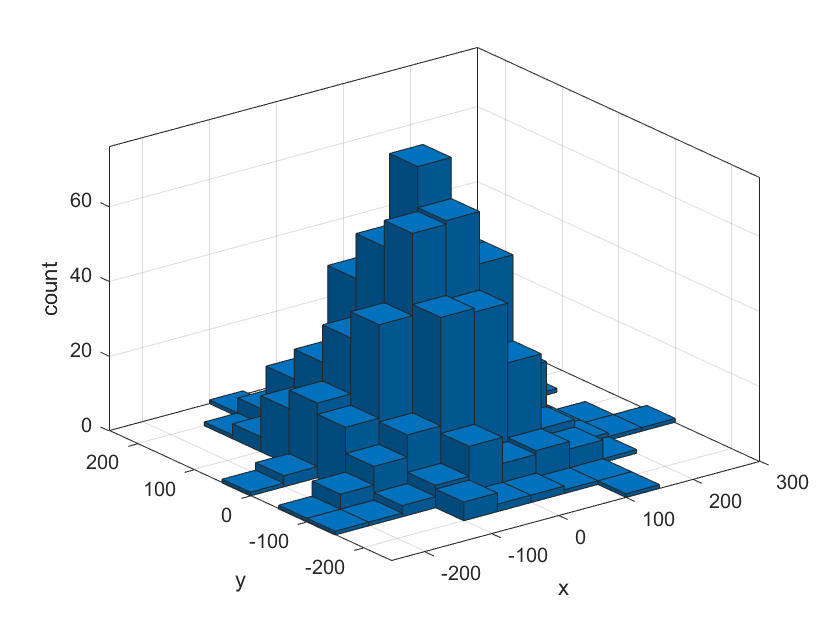

XL = max(abs(x(:)));
YL = max(abs(y(:)));

4. Implement a random walk in **three **dimensions.  Choose from a static image, a slider, or an animation to visualise the results.  Or try all three!

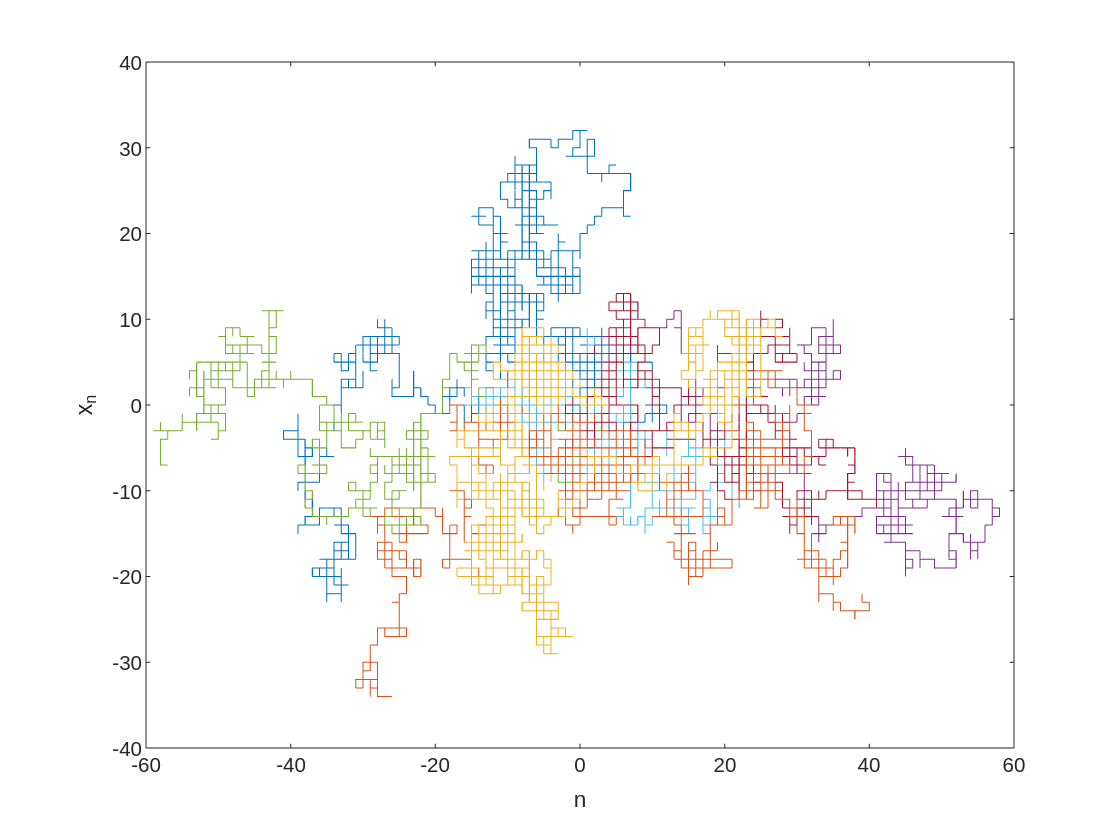

particles = 10;     % number of particles
steps     = 1000;   % number of steps

p         = 0.5;    % probability of jumping left
j = 0.5;
Delta     = 1;      % size of jump

figure

x = zeros(particles,steps+1);
y = zeros(particles,steps+1);
z = zeros(particles,steps+1);

% Code to perform random walk goes here
for n = 1:steps
    for m = 1:particles
        d = rand;
        xyRand = rand;
        


        if xyRand < j
            y(m, n+1) = y(m, n);
            if d < p
                x(m, n+1) = x(m, n) - Delta;	% jump left
            else
                x(m, n+1) = x(m, n) + Delta;	% jump right
            end
        else
            x(m, n+1) = x(m, n);
            if d < p
                y(m, n+1) = y(m, n) - Delta;	% jump down
            else
                y(m, n+1) = y(m, n) + Delta;	% jump up
            end
        end
    end
end

figure
plot(y', x')
xlabel('n')
ylabel('x_n')

# Quiz

The Quiz is your assessment for this topic.  The link can be found on Canvas.  Follow the link to complete the Quiz.